# MATH2089 Week 4 Lab

In this week's lab we examine the *Law of Large Numbers (LLN)* and *Central Limit Theorem (CLT).* The LLN implies that the average of a function of a random sample will converge to the expected value of that function. Symbolically, if $X_{1},\ldots,X_{n}$ is an independent sample from the distribution $F$, then, for any function $g$ (with some mild technical constraints on what types of functions $g$ can be), 

$\frac{1}{n}\sum^{n}_{i = 1} g(X_{i}) \rightarrow \mathbb{E}g(X) = \int_{\mathbb{R}}g(t)f(t)\,\mathrm{d}t$,

where convergence is *in probability (weak LLN)* or *almost surely (strong LLN)*. This is the most important result in statistics and tells us that—for sufficiently large samples—estimates computed from sample averages should approximate the *true value.* The CLT is a subsequent result that describes the distribution of sample averages around the true value. In the simplest case, let $\mu$ and $\sigma$ respectively denote the *finite* mean and standard deviation of $F$, and define the sequence of random variables

$Y_{n} := \sqrt{n}\frac{\overline{X}_{n} - \mu}{\sigma}$,

where $\overline{X}_{n} = n^{-1}\sum^{n}_{i = 1} X_{i}$. Then $Y_{n}\rightarrow N(0,1)$ in distribution—the distribution of $Y_{n}$ converges to the standard Normal distribution, even if we don't know what the exact distribution of $Y_{n}$, or even $F$. The sequence $Y_{1},\dots,Y_{n}$ is called the sequende of *standardised* sample means since 


$$\mathbb{E}Y_{n} = \frac{\sqrt{n}}{\sigma}\left(\mathbb{E}\overline{X}_{n} - \mu\right) = 0$$


and


$$\text{Var}\left(Y_{n}\right) = \frac{n}{\sigma}\text{Var}\left(\overline{X}_{n} - \mu\right) = 1.$$


The CLT is a useful result that gives us more information about how variable our estimates are around the true value. For sufficiently large $n$ we can apply the location-scale structure of the Normal distribution to generate the approximation

$\frac{X_{1} + \cdots + X_{n}}{n} =: \overline{X}_{n}\overset{approx}{\sim}N\left(\mu, \frac{\sigma}{\sqrt{n}}\right)$.

The power of the CLT is that it works as long as the variance of the distribution $\sigma^{2} < \infty$, regardless of the form that the distribution $F$ takes. The upshot is that we can simulate sample means and generate confidence intervals about the population mean using the Normal distribution. Note here that the variance of the sample mean $\text{Var}\left(\overline{X}_{n}\right) = n^{-1/2}\sigma\rightarrow 0$. This implies that the sample mean converges to $\mu$ in *Mean Squared Error*, which itself implies the WLLN. 

## Exercise 2

In this question we'll take a look at the Central Limit Theorem for Bernoulli random variables. Bernoulli distributions can be used to examine population proportions, so applying the CLT will let us make inference on the true population proportion by using the observed sample population proportion and the Normal distribution. Let $X_{1},\ldots,X_{n}$ be an independent sequence of $\text{Ber}(p)$ random variables—recall that $\text{Ber}(p)\equiv\text{Bin}(1, p)$. Then $0 \leq \overline{X}_{n}\leq 1$. Consider a *sequence of *$R$ *samples of size *$n$

$\begin{array}{c}
&\left\{X_{1,1},\ldots,X_{1,n}\right\} \mapsto \overline{X}_{1,n} \\
&\left\{X_{2,1},\ldots,X_{2,n}\right\} \mapsto \overline{X}_{2,n} \\
&\vdots \\
&\left\{X_{R,1},\ldots,X_{R,n}\right\} \mapsto \overline{X}_{R,n} 
\end{array}$,

where $\overline{X}_{1,n},\ldots,\overline{X}_{R,n}$ is the corresponding sequence of sample means. We wish to simulate the sample means. The independence of the data implies that we write the samples into the matrix

$B=\;\left\lbrack \begin{array}{cccc}
X_{11}  & X_{12}  & \cdots \; & X_{1n} \\
X_{21}  & X_{22}  & \cdots  & X_{2n} \\
\vdots  & \cdots  & \ddots  & \vdots \;\\
X_{\textrm{R1}}  & X_{\textrm{R2}}  & \cdots \; & X_{\textrm{Rn}} 
\end{array}\right\rbrack$,

where each row defines a sample. We can then compute the rowwise means. By default, `mean()` computes the *columnwise* means, so we'll need to swap the dimensions of $B$ in its construction—or we could compute rowwise means by writing `mean(_, 2)`. 

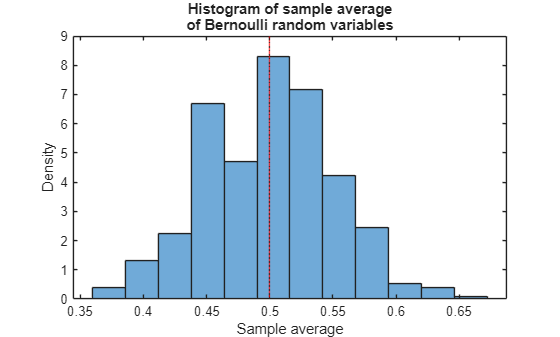

% Set the sample size n
sampleSize = 100;
% Set the number of sample R
numberReplicates = 500;

% Set the Bernoulli parameter p
bernoulliParameter = 0.5;

% Construct an n-by-R matrix of Ber(p) random variables
% See 'help binornd' for details
bernoulliSamples = binornd(1, bernoulliParameter, sampleSize, numberReplicates);

% Compute the columnwise averages of the Bernoulli matrix
sampleAverages = mean(bernoulliSamples);

% plot the histogram of sample averages
numberBins = 12; % play around with the number of bins to make the plot look nice

histogram(sampleAverages, numberBins, 'Normalization','pdf')
title({'Histogram of sample average', 'of Bernoulli random variables'})
xlabel('Sample average')
ylabel('Density')
xline(mean(sampleAverages), "r") % vertical red line for average of sample averages
xline(bernoulliParameter, ':') % vertical dotted line for true Bernoulli parameter

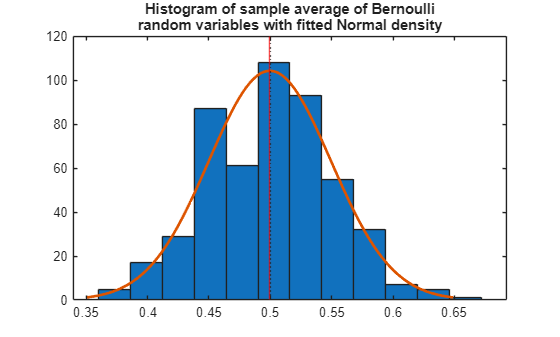


% Overlay the estimated Normal density
histfit(sampleAverages, numberBins)
title({'Histogram of sample average of Bernoulli', 'random variables with fitted Normal density'})
xline(mean(sampleAverages), "r")
xline(bernoulliParameter, ':')

The CLT implies that the sample mean will be Normally distributed. The vertical dotted and red lines indicate the true and empirical mean of the sequence of sample averages. The histogram appears to be roughly bell-shaped about the empirical average, indicating that the sample averages may be Normally distributed. Applying `histfit()` indicates that the sample averages are roughly Normally distributed, even when the generating distribution is not Normal! 

Change $n$ and $R$ to see how the approximation changes. 

We'll use this result to generate confidence intervals—objects which provide some degree of belief where the true parameter is located. 

Theoretically, 


$$\mathbb{E}\overline{X}_{n} = \frac{1}{n}\left(\mathbb{E}X_{1}+\cdots+\mathbb{E}X_{n}\right) = \frac{np}{n} = p$$


and


$$\text{Var}\left(\overline{X}_{n}\right) = \frac{1}{n^{2}}\left(\text{Var}X_{1}+\cdots+\text{Var}X_{n}\right) = \frac{np(1 - p)}{n^{2}} = \frac{p(1 - p)}{n}$$


So, for sufficiently large number of replicate samples $R$, we should expect the *average of the sample averages *to be close to $p$ (`bernoulliParameter`) and the sample variance of the sample averages to be close to $p(1 - p)/n$. The empirical values will converge to the theoretical values as the number of samples $R$ increases. 

% sample average and variance of the Bernoulli sample averages
[mean(sampleAverages), var(sampleAverages)]

ans =     0.4996    0.0025



% The true mean and variance of the Bernoulli sample mean
[bernoulliParameter, bernoulliParameter * (1 - bernoulliParameter) / sampleSize] 

ans =     0.5000    0.0025



% The average of all elements in B. Why is this equal to the average of the
% sample averages?
mean(bernoulliSamples, 'all')

ans = 0.4996


% The variance of all elements in B. Why is this different to the variance
% of the sample averages?
var(bernoulliSamples, 0, 'all') 

ans = 0.2500

## Exercise 3

In the previous question we examined the Central Limit Theorem for a non-Normal discrete distribution. In this question we'll repeat the examination for a non-Normal continuous distribution. Let's first Import the `kevlar90 `dataset and plot the data as a histogram.

kevlar90 = readvars("./data/kevlar90.txt");

% The rule of thumb for histograms is the you should use sqrt(n) bins
numberDataPoints = length(kevlar90);
numberBins = ceil(sqrt(numberDataPoints));

% Plot the histogram
histogram(kevlar90, numberBins, 'Normalization', 'pdf')
xlabel('Failure time (hours)')
ylabel('Density')
title('Density histogram for kevlar90')

It is clear that `kevlar90 `is not Normally distributed since the data do not produce a bell-shaped histogram. The histogram shows that most of the data are concentrated at small positive values, with a thin tail extending out to larger positive values—the data is right-skewed. The data appear to be Exponentially distributed. Recall that the mean and standard deviation of the Exponential distribution are both equal to its parameter $\lambda$. If the sample average and standard deviation are sufficiently close, then we have some (*weak*) evidence that the data is Exponentially distributed.

[mean(kevlar90), std(kevlar90)]

The values of the sample average (1.0239) and sample standard deviation (1.1173) are pretty close, so we have some indication that the positively skewed and positive-valued are Exponentially distributed. The best way to check the distributional fit is to in fact just fit the distribution to the data. Let's use `histfit()` to check this, where we now fit an Exponential distribution. The fitted parameter for the Exponential distribution is the same as the sample average, i.e., $\hat{\lambda} = \overline{x}$. 

histfit(kevlar90, numberBins, 'exponential')

It is now evident that the data `kevlar90 `are most likely Exponentially distributed. We see that the exponential decay in the density resembles the reduced heights of the histogram bars, with the data and density extending into larger positive values. Both the data and histogram are notably asymmetric and are defined for positive values (*the positive *$x$*-axis)*. 

Let's now use the fitted parameter $\hat{\lambda} = \overline{x}$ to simulate more Exponential random variables. 

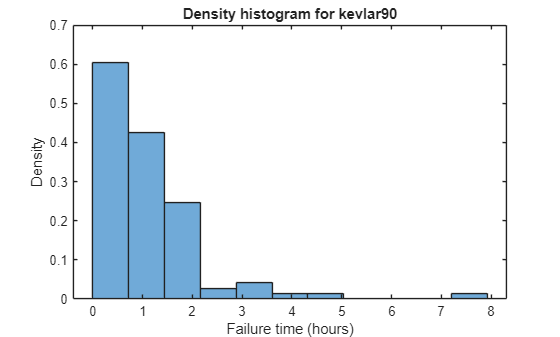

sampleSize = 100;
numberReplicates = 1000;


% The mean of the data shall be the distributional parameter

ans =     1.0239    1.1173


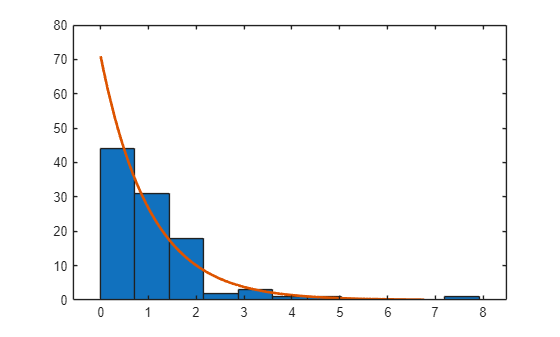

kevlarMean = mean(kevlar90);


exponentialSamples = exprnd(kevlarMean, sampleSize, numberReplicates);
sampleAverages = mean(exponentialSamples);

% The sample average and variance of the Exponential sample averages
[mean(sampleAverages), var(sampleAverages)]
% The true mean and variance of the sample means
[kevlarMean, kevlarMean^2 / sampleSize]

We expect the sample mean to follow a Normal distribution. Let's use `histfit` to compare our theory to our simulated values. The histogram of the standardised sample averages should follow a standard Normal distribution, as shown in the figure below. Recall that the mean and standard deviation for the Exponential distribution are equal to the parameter $\lambda$. Hence, our standardised sample means take the form

$\sqrt{n}\frac{\overline{X}_{n} - \lambda}{\lambda}$,

where $\lambda = \hat{\lambda}$, the sample average of `kevlar90`. The fitted histogram indicates that the sample mean of a set of Exponential random variables will very closely follow a Normal distribution. The shape and variance of a distribution will determine the speef at which it converges to a Normal distribution, although they all do, eventually. 

ans =     1.0265    0.0102


ans =     1.0239    0.0105


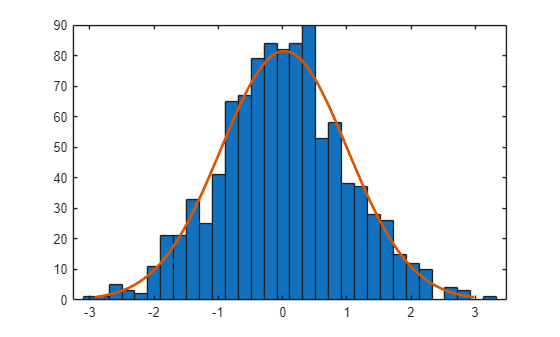

standardisedSampleAverages = sqrt(sampleSize) * (sampleAverages - kevlarMean) / kevlarMean;

histfit(standardisedSampleAverages)